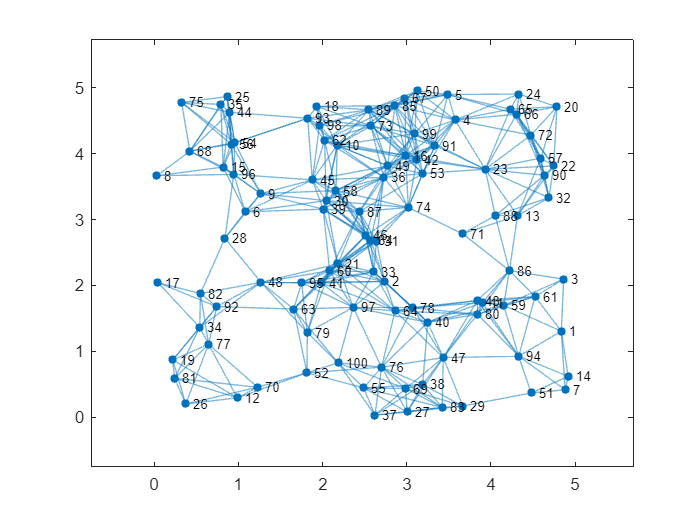

clc;
close all;
import ELSclique.*
rng(4)
N=100;%No of links

x=rand(1,N)*5;
y=rand(1,N)*5;

%scatter(x,y)
%Distance of the nodes
d=zeros(N,N);
for i=1:N
    for j=i+1:N
        d(i,j)=sqrt((x(j)-x(i))^2+(y(j)-y(i))^2);
        d(j,i)=d(i,j);
    end
end

%Selecting those nodes for edges which has distance less than or equal
% to 1

A=zeros(N);
for i=1:N
    for j=i+1:N
        if d(i,j)<=1
            A(i,j)=1;
            A(j,i)=1;
        end
    end
end

[cliques]=ELSclique(A);
log_cliques=full(cliques);
clique_size=zeros(1,size(log_cliques,2));
for i=1:length(clique_size)
     for j=1:size(log_cliques,1)
        if log_cliques(j,i)==1
            clique_size(i)=clique_size(i)+1;
        end    
     end 
end 
%figure(2)
%G=graph(A);
%plot(G,"XData",x,"YData",y)
%{
Adjust the adjacency matrix to ensure no clique is larger than the
maximum clique size
%}
for i = 1:size(log_cliques, 2)
    cliqueNodes = find(log_cliques(:, i)==1);
    if length(cliqueNodes) > 10
        % Remove edges to break the clique
        cliqueEdges = nchoosek(cliqueNodes, 2);
        for j = 1:size(cliqueEdges, 1)
            A(cliqueEdges(j, 1), cliqueEdges(j, 2)) = 0;
            A(cliqueEdges(j, 2), cliqueEdges(j, 1)) = 0;
        end
    end
end

[cliques_re]=ELSclique(A);
log_cliques_re=full(cliques_re);
clique_size_re=zeros(1,size(log_cliques_re,2));
for i=1:length(clique_size_re)
     for j=1:size(log_cliques_re,1)
        if log_cliques_re(j,i)==1
            clique_size_re(i)=clique_size_re(i)+1;
        end    
     end 
end
figure(3)
G_re=graph(A);
plot(G_re,"XData",x,"YData",y)

avl_ch=[2 4 6 8 10];%available channel options
for ch=1:length(avl_ch)
    M=avl_ch(ch);
    N=100;
    w_G=max(clique_size_re);
    s_rmax=min([1 M/w_G])
    load=[0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9];
    choice=load*s_rmax;
    error=zeros(1,9);

    for i1=1:length(choice)
        S_desired=choice(i1);
        ui=S_desired/M;
        uj=S_desired/M;
        exp_ri=zeros(1,N);
        for i=1:N
            li=find(A(i,:)==1);
            di=length(li);
            uij=(ui+uj-1+sqrt(4*(M-1)*ui*uj+(ui+uj-1)^2))/(2*(M-1));
            Prod=ones(1,di)*((ui-(M-1)*uij)/(1-M*(ui+uj-(M-1)*uij)));
            exp_ri(i)=(((1-M*ui)/ui)^(di-1))*prod(Prod);
        end
        num_iter=1e7;
        B=zeros(num_iter,N);
        for i=2:size(B,1)
            index=1:N;
            j=randi(N);
            index(j)=[];
            a=find(A(j,:)==1);
            Ch=1:M;
            a_ch=B(i-1,a);
            a_ch=unique(a_ch);
            rem_ch=Ch(~ismember(Ch,a_ch));
            if isempty(rem_ch)
                B(i,j)=0;
                B(i,index)=B(i-1,index);
                continue
            end
            p0=1/(1+length(rem_ch)*exp_ri(j));
            p1=1-(1/(1+length(rem_ch)*exp_ri(j)));
            state=[0 rem_ch];
            P1=ones(1,length(rem_ch));
            P1=P1*(p1/length(rem_ch));
            probabilities=[p0 P1];
            s=randsample(state,1,true,probabilities);
            random=rand;
            if random>p1
               B(i,j)=0;
               B(i,index)=B(i-1,index);
            else
                B(i,j)=rem_ch(randi(length(rem_ch)));
                B(i,index)=B(i-1,index);
            end
        end

        S_rempirical=zeros(1,N);
        for i=1:N
            on=transpose(find(B(:,i)>0));
            S_rempirical(i)=length(on)/num_iter;
        end

        el_error=zeros(1,N);
        for i=1:N
            error_ch=[S_desired-S_rempirical(i) 0];
            el_error(i)=max(error_ch)/S_desired;
        end
        error(i1)=(100/N)*sum(el_error);
    end
    plot(load,error,"-*","LineWidth",1.5)
    xlabel("load")
    ylabel("error")
    hold on
end

s_rmax = 0.2500

s_rmax = 0.5000

s_rmax = 0.7500

s_rmax = 1

s_rmax = 1

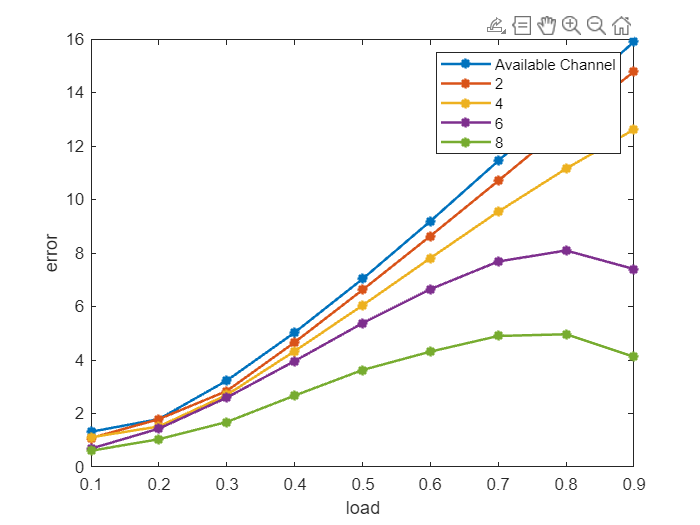

legend("Available Channel","2","4","6","8","10")